% Load the training data 
data = load("aug4signs_trainingdata.mat");
trainingData = data.trainingData;


% Create an imageDatastore using the files from the table.
imds = imageDatastore(trainingData.imageFilename);

% Create a boxLabelDatastore using the label columns from the table.
blds = boxLabelDatastore(trainingData(:,2:end));

% Combine the datastores.
ds = combine(imds, blds);

detector = yolov4ObjectDetector("tiny-yolov4-coco");
detector.Network;

% Specify the input size
inputSize = [224 224 3];

trainingDataForEstimation = transform(ds,@(data)preprocessData(data,inputSize));

numAnchors = 6;
[anchors, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);
area = anchors(:,1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:);anchors(4:6,:)};


classes = {'TrafficSign'};
detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,anchorBoxes,InputSize=inputSize);


options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MiniBatchSize=16,...
    MaxEpochs=50, ...
    BatchNormalizationStatistics="moving",...
    ResetInputNormalization=false,...
    VerboseFrequency=5, ...
    Plots="training-progress");


*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* TrafficSign

 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss
    _____    _________    ___________    _________    ____________
      1          5         00:00:24        0.001         17.065   
      2         10         00:00:44        0.001         20.32    
      3         15         00:01:10        0.001         12.53    
      4         20         00:01:40        0.001         8.2149   
      5         25         00:02:10        0.001         6.2812   
      5         30         00:02:32        0.001         11.246   
      6         35         00:02:56        0.001         3.7155   
      7         40         00:03:20        0.001         2.2846   

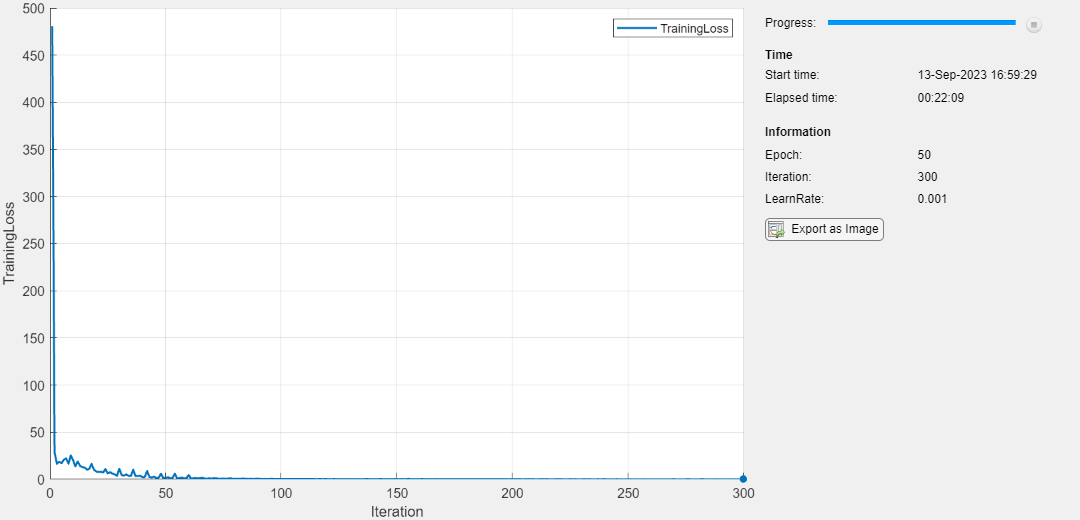

     50         300        00:22:05        0.001        0.040383  

*************************************************************************
Detector training complete.
*************************************************************************



% Train the YOLO v4 network.
trainedDetector_4signs = trainYOLOv4ObjectDetector(ds,detector,options);

save('aug4signs_yolov4_50e.mat','trainedDetector_4signs');


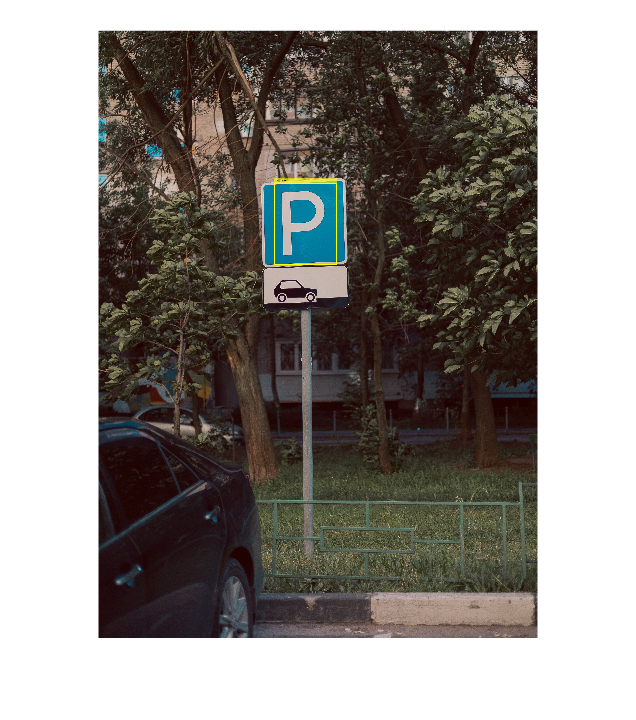

I = imread("C:\Users\Calm\Downloads\testing-signs\parking\parking (2).jpg");

[bboxes, scores, labels] = detect(aug4signs_yolov4_10e,I,Threshold=0.05);
detectedImg = insertObjectAnnotation(I,"Rectangle",bboxes,labels,"LineWidth",8,"FontSize",24);
figure
imshow(detectedImg)

function data = preprocessData(data,targetSize)
for num = 1:size(data,1)
    I = data{num,1};
    imgSize = size(I);
    bboxes = data{num,2};
    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    data(num,1:2) = {I,bboxes};
end
end